# Count pills

## Count pills

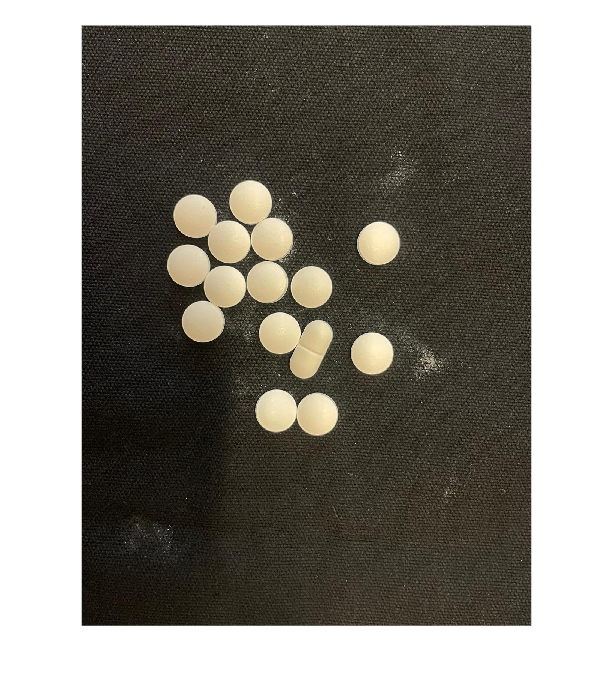

pills = imread("C:\Users\Lola Monroy Mir\OneDrive\Escritorio\Matlab_Lauz\pill1.jpeg"); % change pill number
imshow(pills)

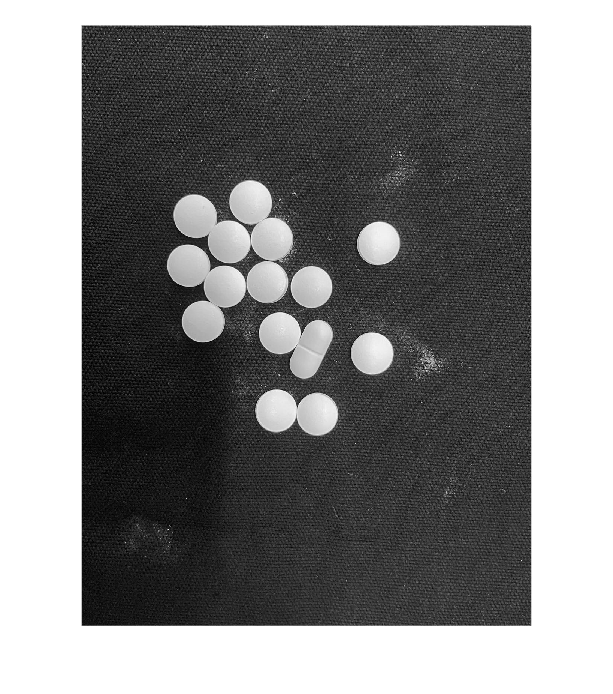

% from colour to BnW
pills_g = rgb2gray(pills);
imshow(pills_g)

Now, we binarize the image. I do this using the threshold method, choosing a number that is somewhere in the middle as the threshold value. I have tried Otsu's method of finding a threshold with the graythres() function, but I found that the half-way method obtained better results, removing noise more efficiently. In particular, a threshold of 180 seems to provide the most satisfactory balance in binarization for our purpose.

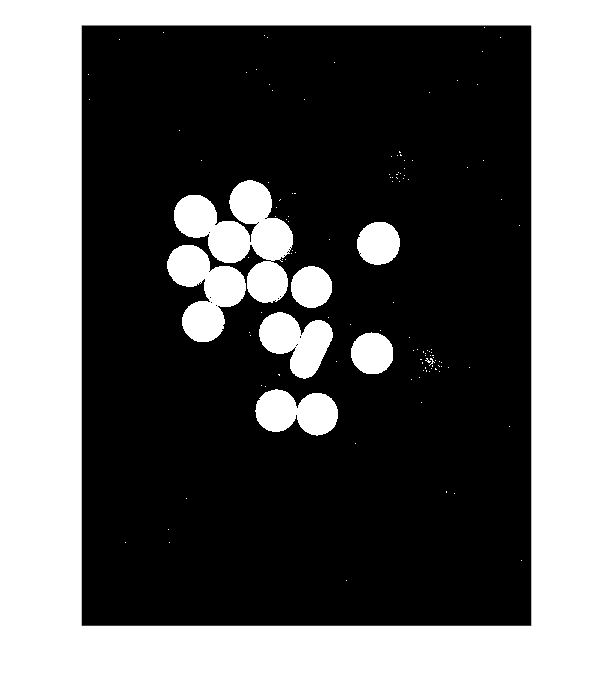

threshold = 160; 
pills_bin = pills_g > threshold;
imshow(pills_bin)

We see that there is noise caused by the light reflecting off the background. We only want the pills to be white. To fix this, I apply a structural element to remove noise. The radius of this is larger than the noise points, but smaller than the pills. In this way, the points are removed, since they are smaller than the structural element, which is what we want.

Since we can count the number of chips with the human eye, they will be counted as a single connected component, even though they are connected by as little as one pixel. Therefore, it is necessary to make each chip a connected component independent of its neighbors in order to apply the function that will count components. Therefore, I will now erode the elements so that they are separated. A structural element of the shape of the disk and large enough, will make the chips smaller so that they are separated but do not disappear completely (obviously).

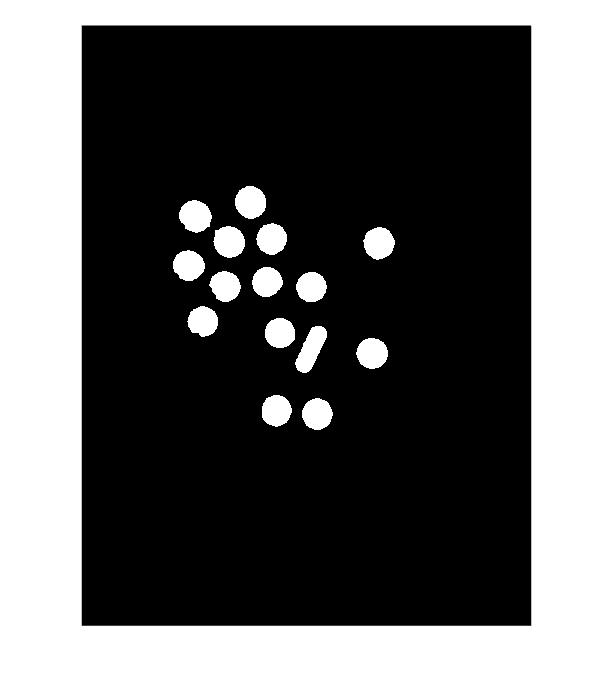

SE2 = strel("disk", 15);  
pills_erode = imerode(pills_bin, SE2);
imshow(pills_erode)

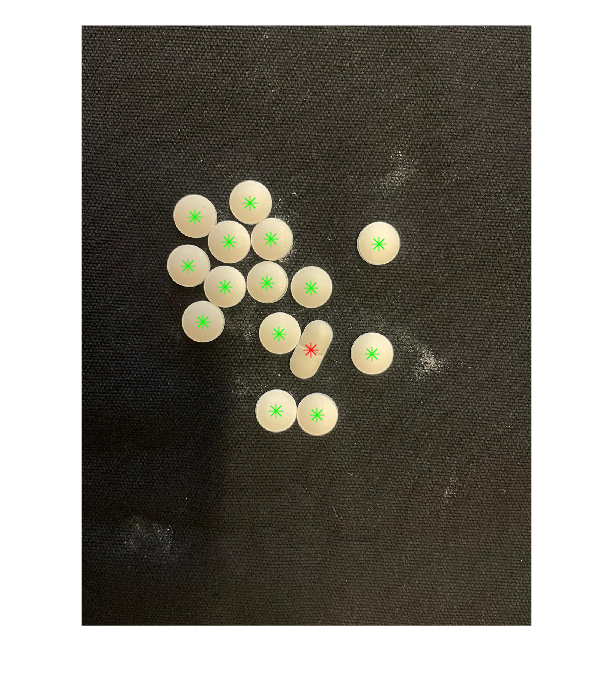

% Label objects
[labeledImage, numObjects] = bwlabel(pills_erode);
stats = regionprops(labeledImage, 'MajorAxisLength', 'MinorAxisLength', 'Eccentricity', 'Centroid', 'BoundingBox');

% Initialize counters
numLong = 0;
numRound = 0;
indicesLong = [];
indicesRound = [];

% Classify objects
figure, imshow(pills), hold on;
for k = 1:numObjects
    aspectRatio = stats(k).MajorAxisLength / stats(k).MinorAxisLength;
    eccentricity = stats(k).Eccentricity;
    centroid = stats(k).Centroid;
    
    % Adjust classification criteria
    if eccentricity > 0.7
        % Long pills
        numLong = numLong + 1;
        indicesLong = [indicesLong, k]; % Store the index of the long pill
        plot(centroid(1), centroid(2), 'r*', 'MarkerSize', 10); % Mark in red
    else
        % Round pills
        numRound = numRound + 1;
        indicesRound = [indicesRound, k]; % Store the index of the round pill
        plot(centroid(1), centroid(2), 'g*', 'MarkerSize', 10); % Mark in green
    end
end
hold off;

% Mostrar resultados
disp(['Number of long pills: ', num2str(numLong)]);

Number of long pills: 1


disp(['Number of round pills: ', num2str(numRound)]);

Number of round pills: 14


## Point

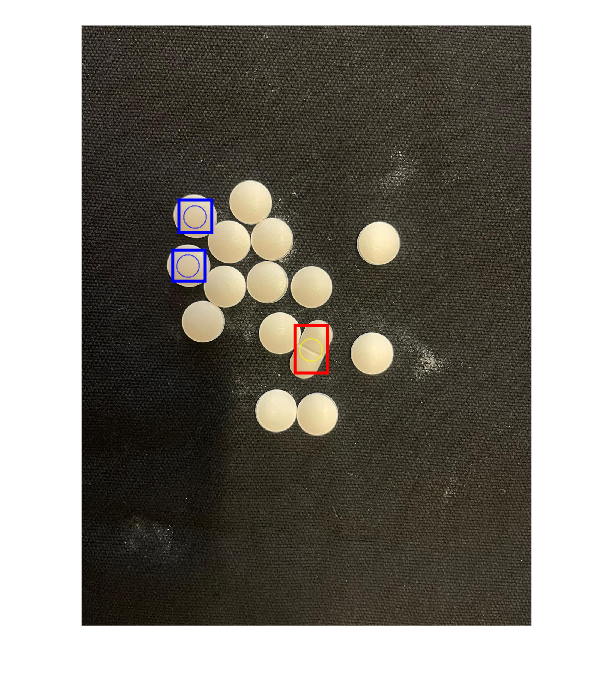

point_round = 2; % Number of round pills to highlight
point_long = 1;  % Number of long pills to highlight

% Highlight specific pills (e.g., two round pills and one long pill)
figure, imshow(pills), hold on;

% Highlight round pills
if numel(indicesRound) < point_round
    disp(['Error: ', num2str(point_round), ' round pills are required, but only ', num2str(numel(indicesRound)), ' were found.']);
else % numel(indicesRound) >= point_round
    for i = 1:point_round
        centroid = stats(indicesRound(i)).Centroid;
        rectangle('Position', stats(indicesRound(i)).BoundingBox, 'EdgeColor', 'blue', 'LineWidth', 2);
        plot(centroid(1), centroid(2), 'bo', 'MarkerSize', 15); % Highlight in blue
    end
end

% Highlight long pills
if numel(indicesLong) < point_long
    disp(['Error: ', num2str(point_long), ' long pill is required, but only ', num2str(numel(indicesLong)), ' was found.']);
else % numel(indicesLong) >= point_long
    centroid = stats(indicesLong(1)).Centroid;
    rectangle('Position', stats(indicesLong(1)).BoundingBox, 'EdgeColor', 'red', 'LineWidth', 2);
    plot(centroid(1), centroid(2), 'yo', 'MarkerSize', 15); % Highlight in yellow
end

hold off;